## Mikołaj Suchoń Lab 4

Task 1)

Task 2)

clear
c1=1;
c2=2;
k1=3;
k2=4;
m1=5;
m2=6;
F=7;

A

%transmitnce
M=[m1 0;0 m2];
C2=[c1 -c1;-c1 (c1+c2)];
K=[k1 -k2;-k1 k1+k2];

%transmittance
s = tf('s');
T = 1/(M.*s^2+C2.*s+K)

T =
 
  From input 1 to output...
              0.2 s^2 + 0.1 s + 0.2333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
                   0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
  From input 2 to output...
                 0.03333 s + 0.1333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
            0.1667 s^2 + 0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
Continuous-time transfer function.




%state
A=[c1/m1 0 k1/m1 0; c1/m1 (-c1-c2)/m2 k1/m2 (-k1-k2)/m2;
    1 0 0 0; 0 1 0 0];
B=[1/m1;0;0;0];
C=[0 0 1 0; 0 0 0 1];
D=[0];
%state space
sys = ss(A,B,C,D);
H=tf(sys)

H =
 
  From input to output...
              0.2
   1:  -----------------
       s^2 - 0.2 s - 0.6
 
                      0.04 s + 0.1
   2:  -------------------------------------------
       s^4 + 0.3 s^3 + 0.4667 s^2 - 0.5333 s - 0.7
 
Continuous-time transfer function.



B)

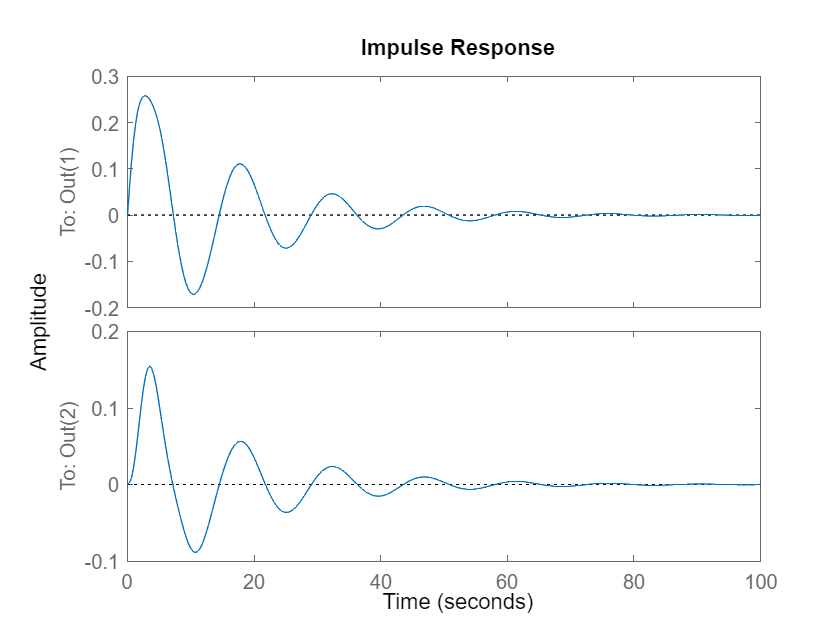

figure(1)
impulse(T(:,1))

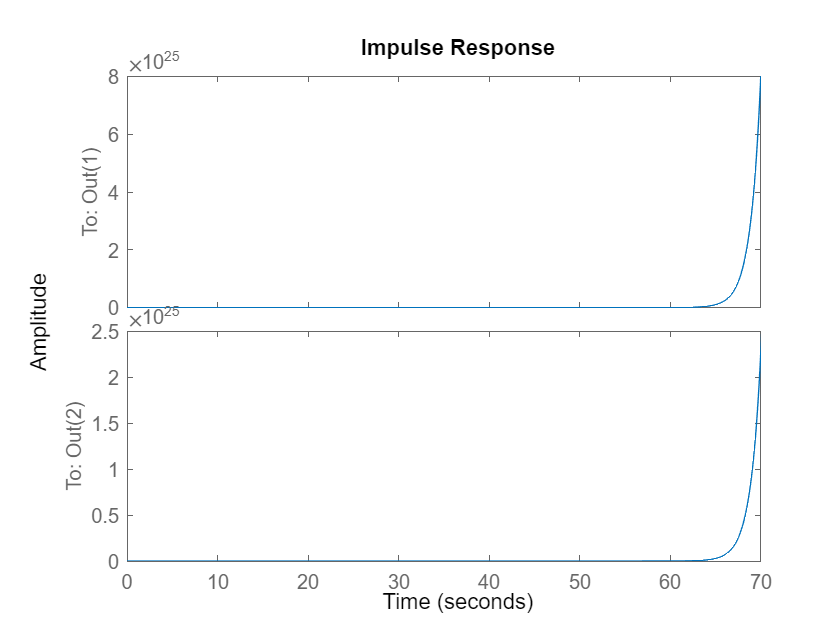

figure(2)
impulse(H)

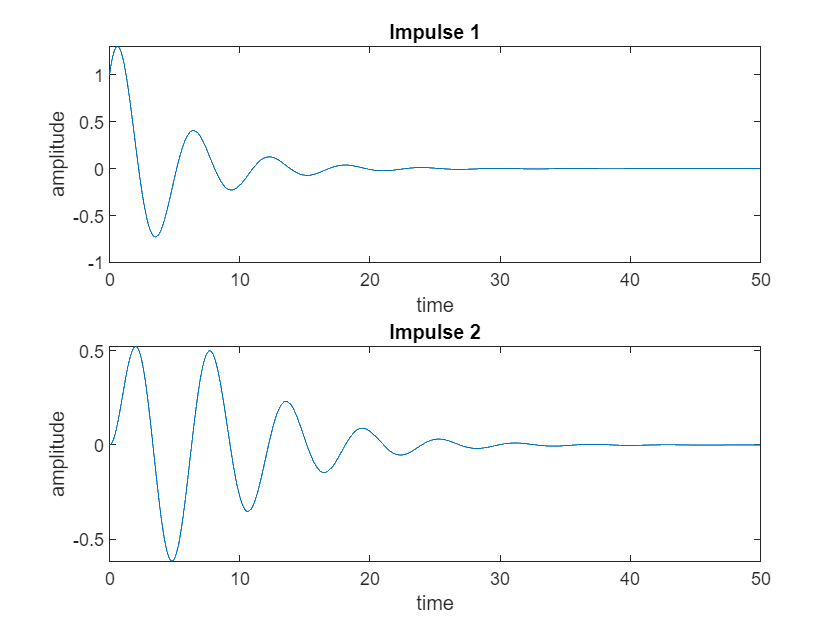

out=sim("reportsim.slx");

figure(3)
subplot(2,1,1)
plot(out.impulse1);
title('Impulse 1')
xlabel('time')
 ylabel('amplitude')
subplot(2,1,2)
plot(out.impulse2);
title('Impulse 2')
xlabel('time')
 ylabel('amplitude')

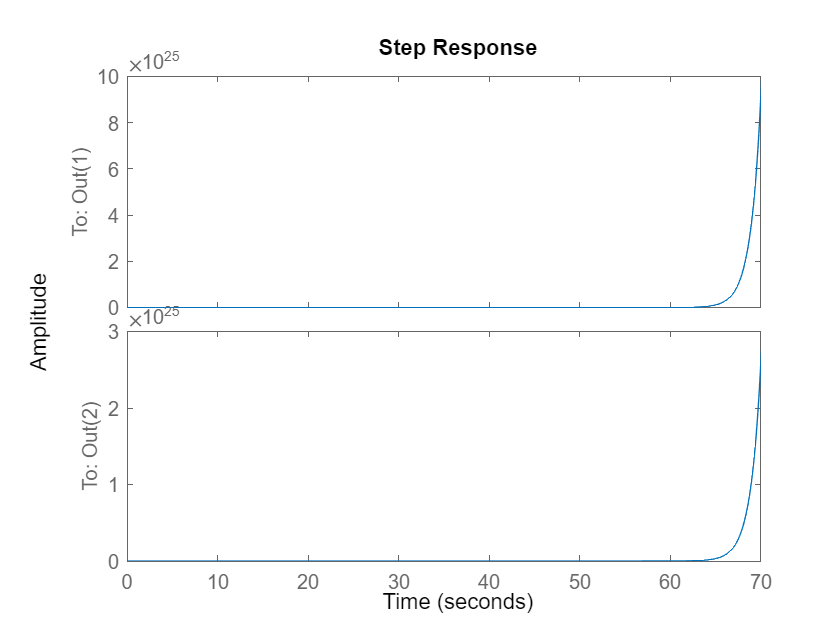

figure(4)
step(H(:,1))

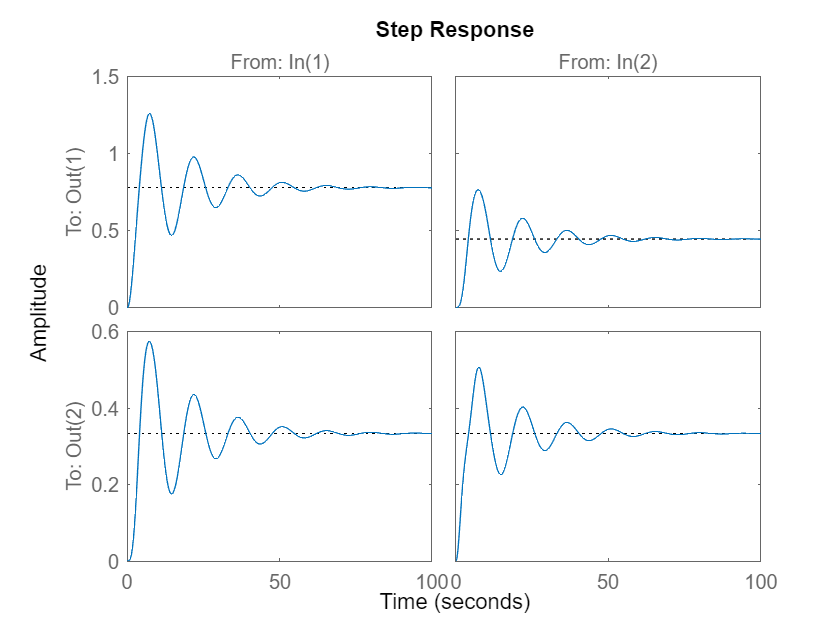

figure(5)
step(T)

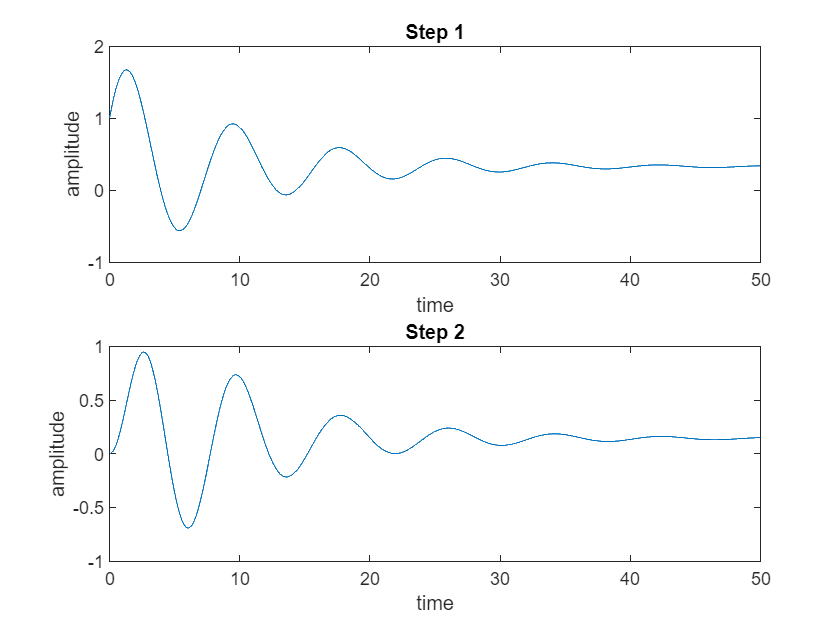

figure(6)
subplot(2,1,1)
plot(out.step1);
title('Step 1')
xlabel('time')
 ylabel('amplitude')
subplot(2,1,2)
plot(out.step2);
title('Step 2')
xlabel('time')
 ylabel('amplitude')

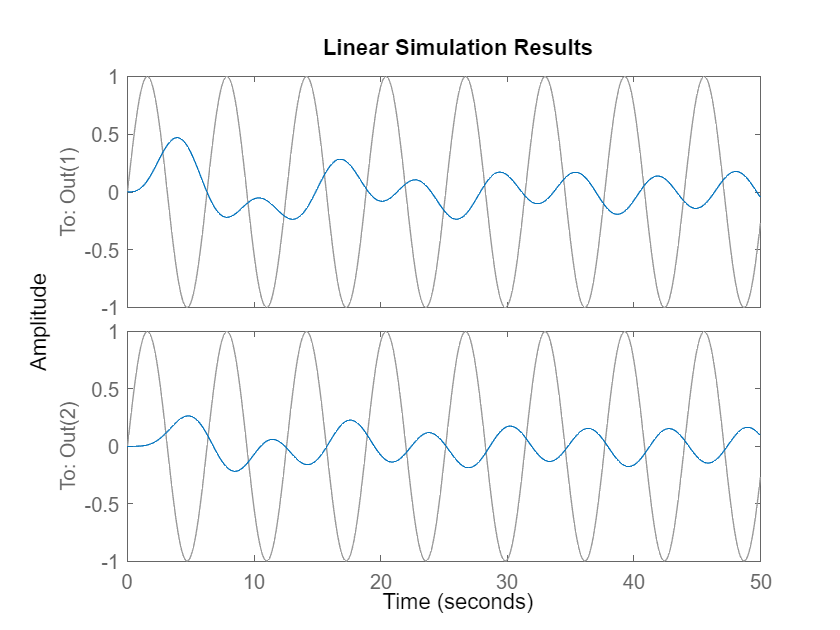

figure(7)
t=0:0.1:50;
y=sin(t);
lsim(T(:,1),y,t);

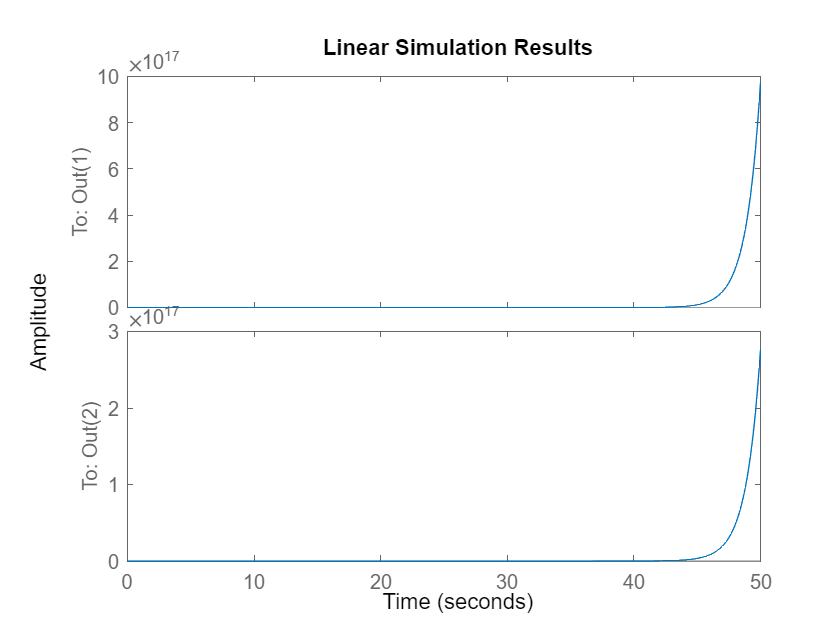

figure(8)
lsim(H(:,1),y,t);

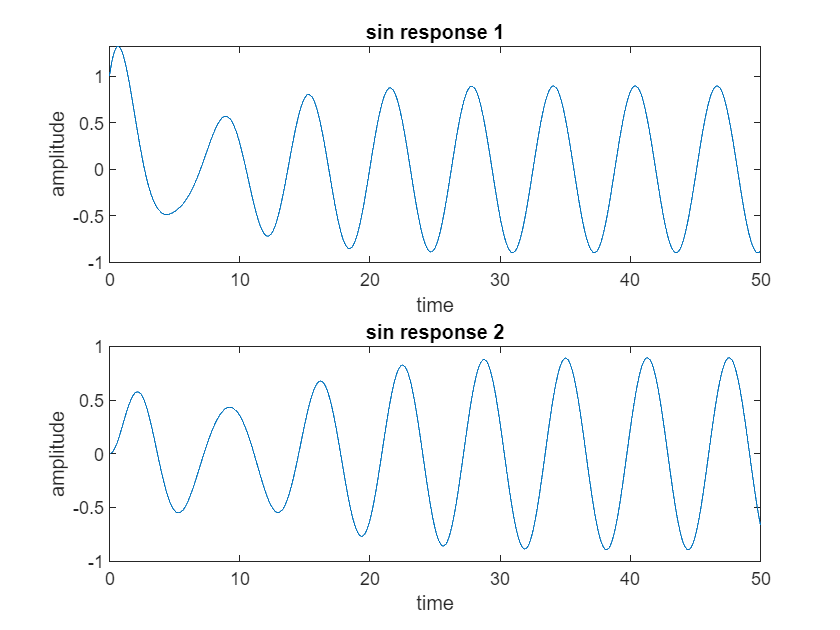

figure(9)
subplot(2,1,1)
plot(out.sin1);
title('sin response 1')
  xlabel('time')
 ylabel('amplitude') 
subplot(2,1,2)
plot(out.sin2);
title('sin response 2')
  xlabel('time')
 ylabel('amplitude')      

D)

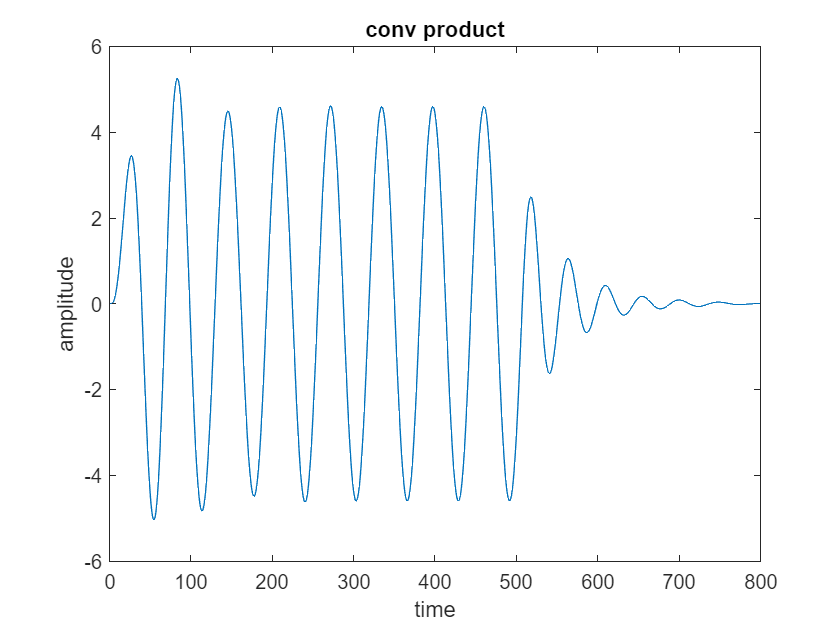

figure(10);
[Y,~] = impulse(T);
x=conv(y,Y(:,1));
 plot(x)
 title('conv product')
 xlabel('time')
 ylabel('amplitude')

Task 3)

 c3=2.5;
k3=5.5;
 %transmitnce
M2=[m1 0;0 m2];
C3=[c1+c2 -c3;-c2 c2+c3];
K2=[k1+k2 -k2;-k2 k2+k3];

%transmittance
s2 = tf('s');
T2 = 1/(M2.*s^2+C3.*s+K2)

T2 =
 
  From input 1 to output...
               0.2 s^2 + 0.15 s + 0.3167
   1:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
                   0.06667 s + 0.1333
   2:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
  From input 2 to output...
                   0.08333 s + 0.1333
   1:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
              0.1667 s^2 + 0.1 s + 0.2333
   2:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
Continuous-time transfer function.



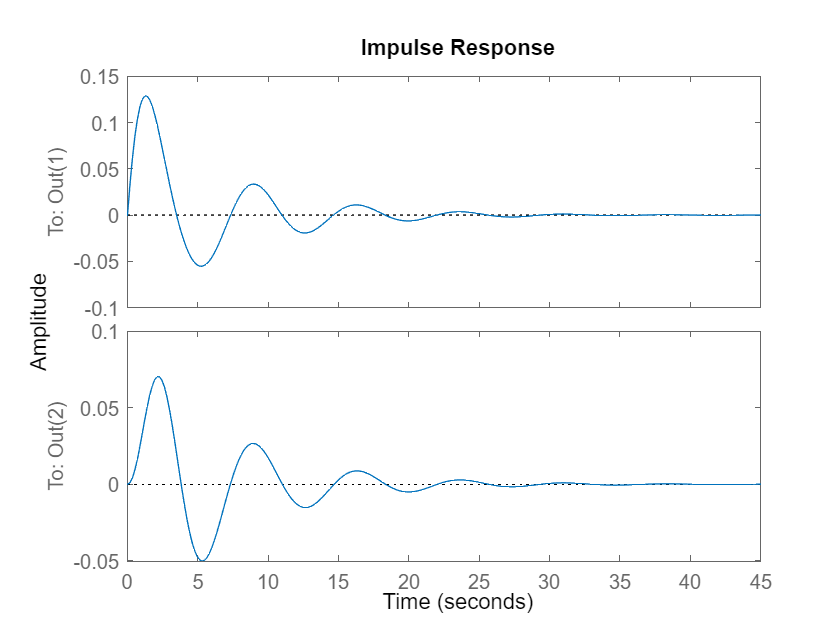


%state
A2=[-(c1+c2)/m1 c2/m1 -(k1+k2)/m1 k2/m1;...
    c2/m2 -(c2+c3)/m2 k2/m2 -(k2+k3)/m2;...
    1 0 0 0;0 1 0 0];
B2=[1/m1;0;0;0];
C4=[0 0 1 0; 0 0 0 1];
D=0;
%state space
sys2 = ss(A2,B2,C4,D);
H2=tf(sys2);
impulse(H2)

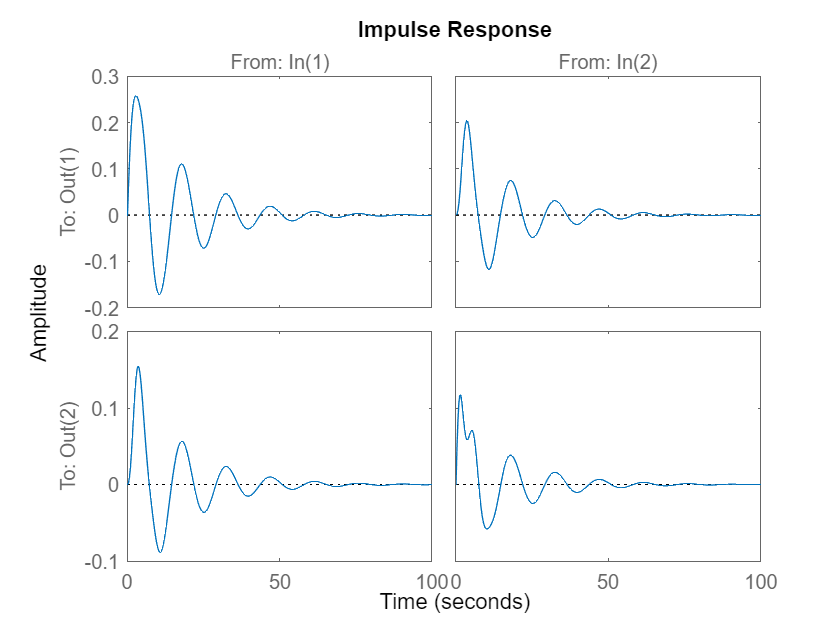

impulse(T)

Task 4)

clear
n=7;
m=n*0.2; 
k=n*5;
c=n*0.3;


A = [-c/m -k/m; 1 0];
B = [-1/m 0]';
C = [0 1];
D = 0;

s = tf('s');
sys = 1/(m*s^2+c*s+k)

sys =
 
           1
  --------------------
  1.4 s^2 + 2.1 s + 35
 
Continuous-time transfer function.



nfreq=sqrt(k/m)

nfreq = 5

dc=c/(2*sqrt(k*m))

dc = 0.1500

dnfreq=nfreq*sqrt(1-dc^2)

dnfreq = 4.9434

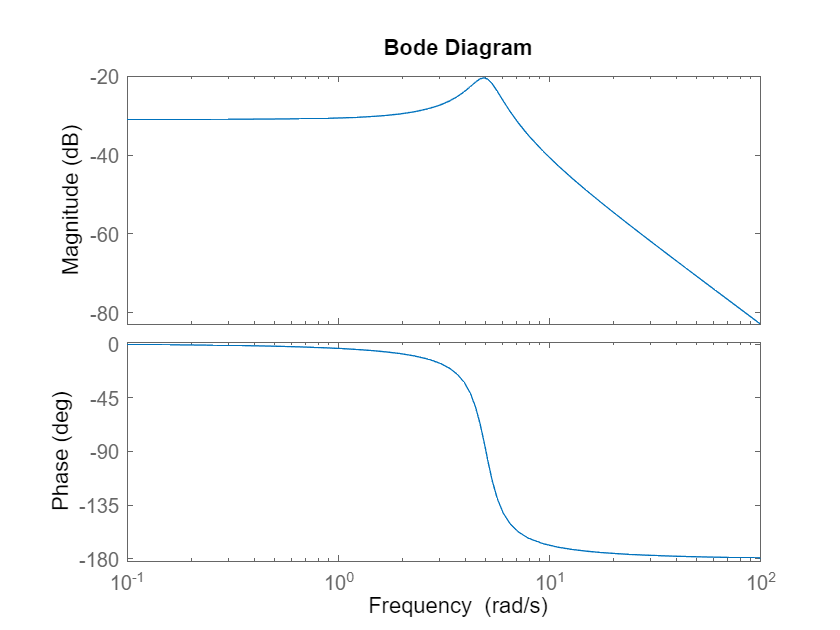


bode(sys.Numerator,sys.Denominator)

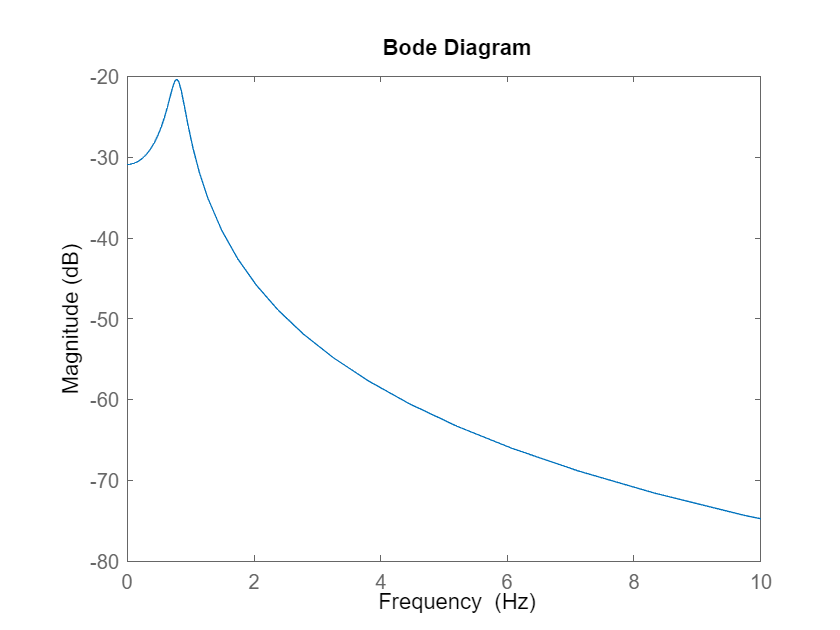

%adjusting bode plot (linear)
set = bodeoptions('cstprefs');
set.FreqUnits = 'Hz';
set.FreqScale = 'linear';
set.PhaseVisible = 'off';
%adjusting bode plot 2 (log)
set2 = bodeoptions('cstprefs');
set2.FreqUnits = 'Hz';
set2.FreqScale = 'log';
set2.PhaseVisible = 'off';
%plotting

bodeplot(sys,set);

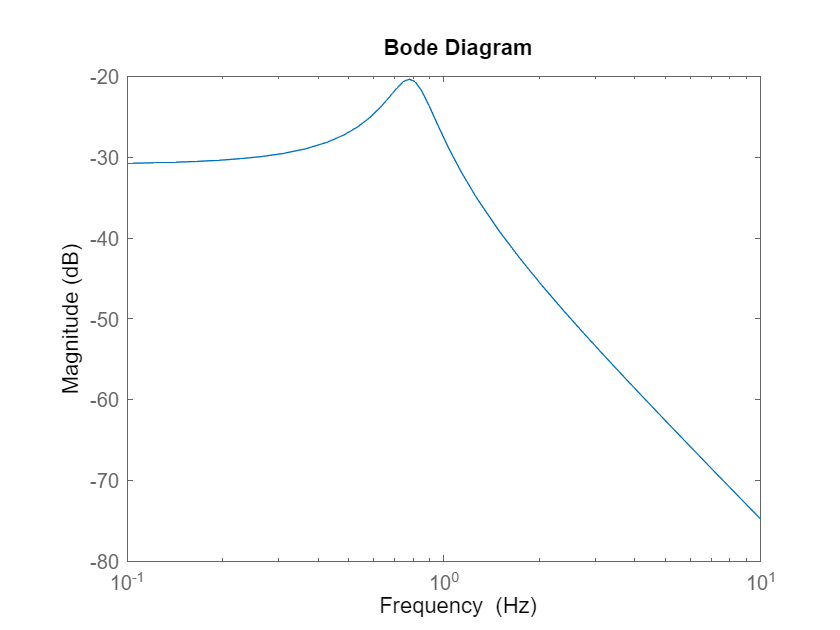


bodeplot(sys,set2);

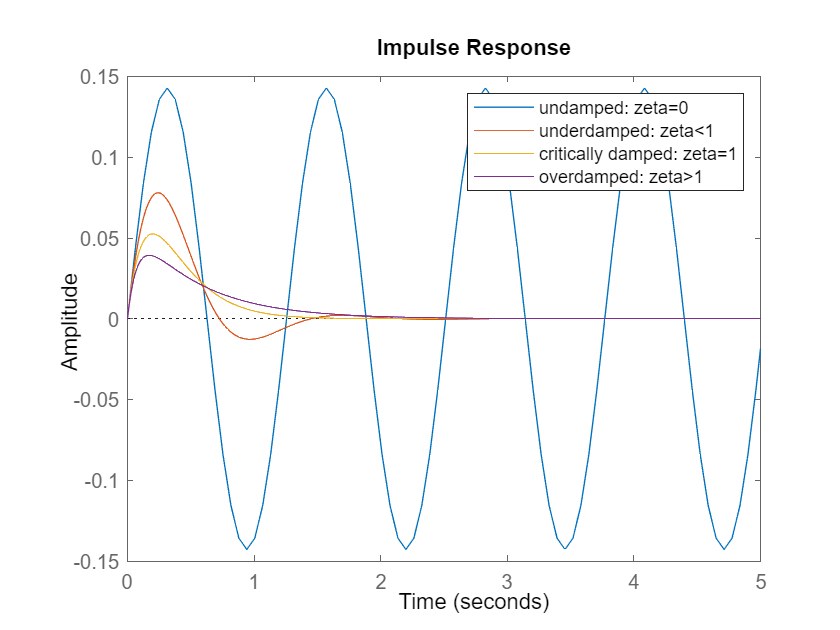

clear 

n=7;
m=n*0.2;
c=n*0.3;
k=n*5;
s=tf('s');
dc=(2*sqrt(k*m));
cun=0;
cu=dc/2;
cc=dc;
co=dc*1.5;


%impulse response

H=1/(m*s^2+cun*s+k);
impulse(H);
hold on;
H=1/(m*s^2+cu*s+k);
impulse(H);
H=1/(m*s^2+cc*s+k);
impulse(H);
H=1/(m*s^2+co*s+k);
impulse(H);
hold off;
xlim([0 5])
legend( ...
    'undamped: zeta=0', ...
    'underdamped: zeta<1', ...
    'critically damped: zeta=1', ...
    'overdamped: zeta>1')

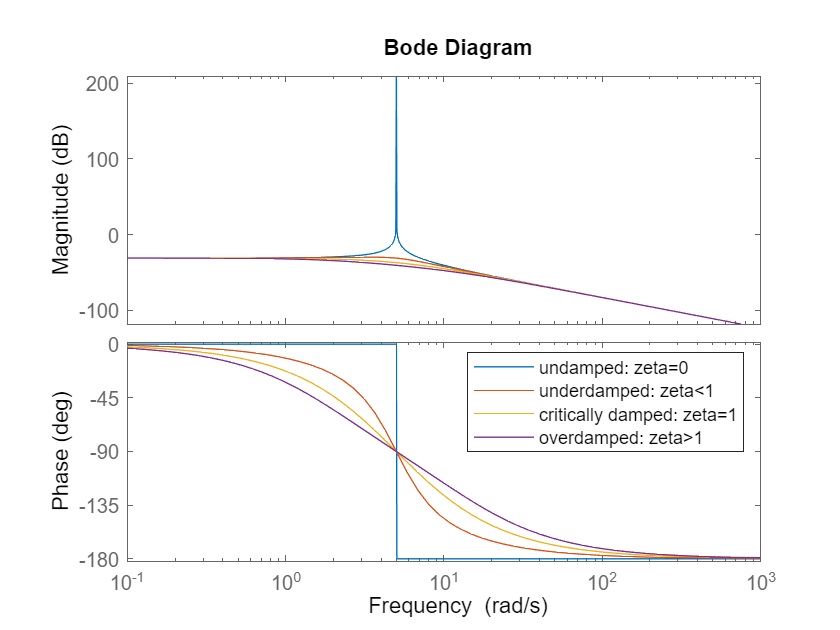


%bode plots


H=1/(m*s^2+cun*s+k);
bode(H);
hold on
H=1/(m*s^2+cu*s+k);
bode(H);
H=1/(m*s^2+cc*s+k);
bode(H);
H=1/(m*s^2+co*s+k);
bode(H);
%xlim([0 5])
legend( ...
    'undamped: zeta=0', ...
    'underdamped: zeta<1', ...
    'critically damped: zeta=1', ...
    'overdamped: zeta>1')